Заметим, что одиночный треугольный импульс длительности $\tau$ и амплитуды A можно представить как результат свёртки прямоугольного импульса:

$p(x) = \sqrt {2A/\tau} \cdot \Pi _{\tau/2} (x)$ длительности $\frac{\tau }{2}$ и амплитуды $\sqrt{2A/\tau}$ с самим собой.

По теореме о свёртке спектра для прямоугольного импульса:


$$F\left\lbrace x_1 \left(t\right)\otimes x_2 \left(t\right)\right\rbrace \left(f\right)=\;X_1 \left(f\right)\cdot X_2 \left(f\right)={\left(\frac{\tau }{2}\;\sqrt{2\frac{A}{\tau }}\;\textrm{sinc}\;\left(\omega \frac{\tau }{4}\right)\right)}^2 =A\frac{\tau }{2}{\textrm{sinc}}^{2\;} \left(\omega \frac{\tau }{4}\right)$$


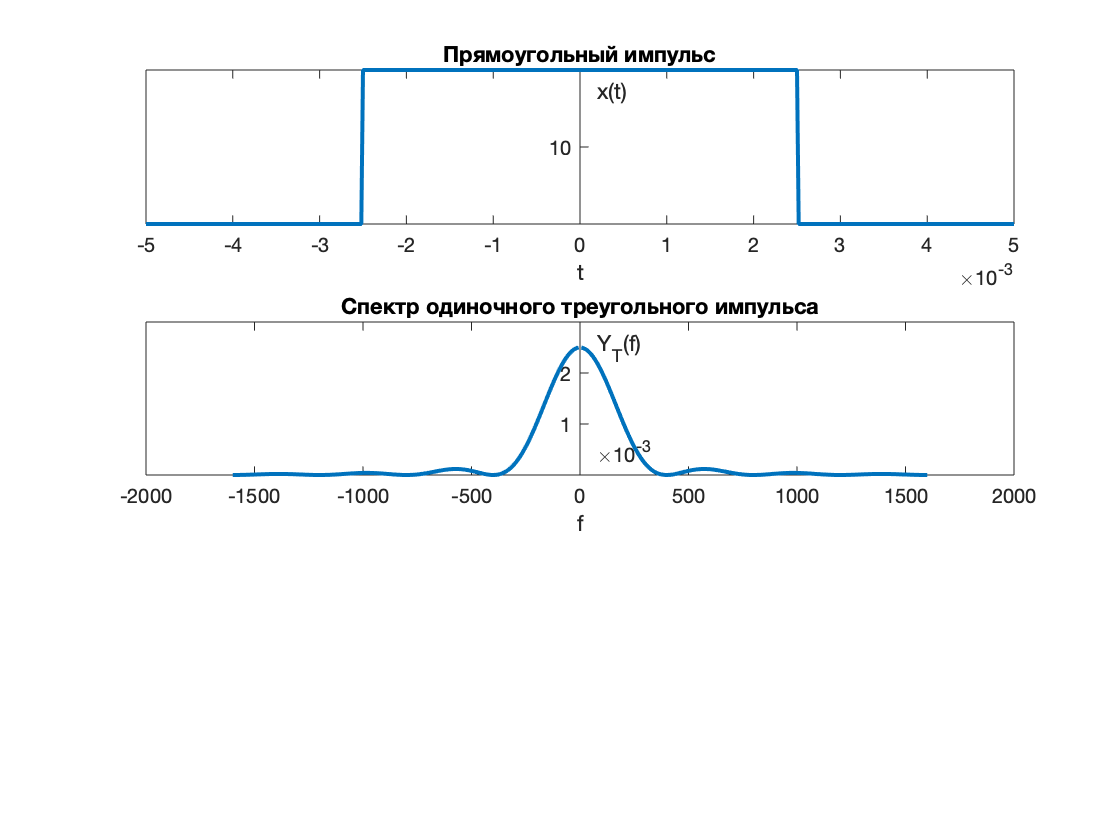

    
tau=5./10^3; 
f0=1./tau;  
E=1;
f=linspace(-8*f0, 8*f0, 513);
t=linspace(-tau, tau, 513); 
xt=sqrt(2.*E./tau).*[zeros(1,(numel(t)-1)/4), ones(1,((numel(t))-1)/2+1), zeros(1,(numel(t)-1)/4)];
XTf=sin(2.*pi.*tau./4.*f)./(2.*pi.*f.*tau./4);
Yf=E.*tau./2.*XTf.*XTf;
% Строим графики
figure;
subplot1 = subplot(3,1,1); plot(t, xt,'LineWidth',2);
set(subplot1,'XAxisLocation','origin','YAxisLocation','origin');
xlabel('t'); ylabel('x(t)'); title('Прямоугольный импульс');
subplot3 = subplot(3,1,2); plot(f, Yf, 'LineWidth', 2);
set(subplot3,'XAxisLocation','origin','YAxisLocation','origin');
xlabel('f'); ylabel('Y_T(f)'); title('Спектр одиночного треугольного импульса');

  Итого, амплитуда центрального лепестка $A\frac{\tau }{2}=0,\textrm{025}$, бокового - 0,0012 

Ответ: 0,024